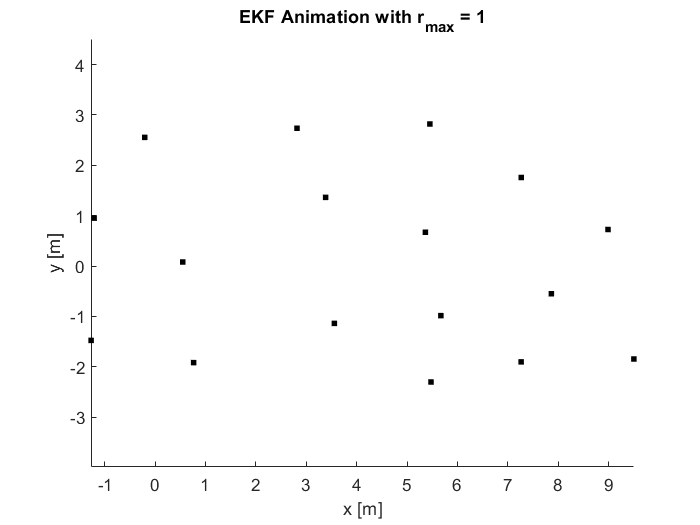

% Load the dataset
load('dataset2.mat');

% Initialize variables
num_timesteps = length(t);
x_est = zeros(num_timesteps, 3); % [x, y, theta] estimates
P_est = zeros(3, 3, num_timesteps); % Covariance matrix

% Initial condition
x_est(1, :) = [x_true(1), y_true(1), th_true(1)];
P_est(:, :, 1) = diag([1, 1, 0.1]); % Initial covariance
Q_k = diag([v_var, om_var]);

% Set r_max for measurement range
r_max = 1;

figure;
hold on;
plot(l(:, 1), l(:, 2), 'k.', 'MarkerSize', 10); % Static landmarks
axis equal;
% xlim([-10, 10]);
% ylim([-10, 10]);
xlabel('x [m]');
ylabel('y [m]');
title(['EKF Animation with r_{max} = ', num2str(r_max)]);

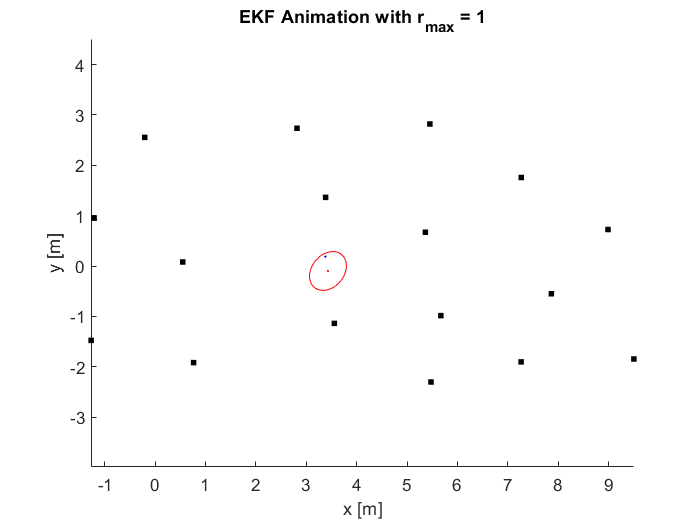


% EKF loop
for k = 2:num_timesteps
    % Time step
    T = t(k) - t(k-1);

    % Previous state
    x_prev = x_est(k-1, :)';
    v_k = v(k);
    omega_k = om(k);
    
    % Prediction step
    F_km1 = [1, 0, -v_k * sin(x_prev(3)) * T;
             0, 1, v_k * cos(x_prev(3)) * T;
             0, 0, 1];
    B_km1 = [T * cos(x_prev(3)), 0;
             T * sin(x_prev(3)), 0;
             0, T];
    
    % State prediction
    x_pred = x_prev + T * [v_k * cos(x_prev(3));
                           v_k * sin(x_prev(3));
                           omega_k];
    P_pred = F_km1 * P_est(:, :, k-1) * F_km1' + B_km1 * Q_k * B_km1';

    % Measurement update with visible landmarks
    visible_landmarks = find((r(k, :) ~= 0) & (r(k, :) <= r_max));
    G_k = [];
    N_k = [];
    z_k = [];
    z_pred = [];
    
    for landmark = visible_landmarks
        lx = l(landmark, 1);
        ly = l(landmark, 2);
        
        % Measurement model
        a = lx - x_pred(1);
        b1 = ly - x_pred(2);
        c = sqrt(a^2 + b1^2);
        
        r_pred = c;
        phi_pred = atan2(b1, a) - x_pred(3);
        
        % Measurement Jacobian
        G_k_l = [-a / c, -b1 / c, 0;
                  b1 / c^2, -a / c^2, -1];
        
        % Stack G_k and measurement noise
        G_k = [G_k; G_k_l];
        N_k_l = diag([r_var, b_var]);
        N_k = blkdiag(N_k, N_k_l);
        
        % Stack measurements and predictions
        z_k = [z_k; r(k, landmark); b(k, landmark)];
        z_pred = [z_pred; r_pred; phi_pred];
    end

    if ~isempty(visible_landmarks)
        S_k = G_k * P_pred * G_k' + N_k;
        K_k = P_pred * G_k' / S_k;
        innovation = z_k - z_pred;
        
        % Angle wrapping for the bearing
        for i2 = 2:2:length(innovation)
            innovation(i2) = mod(innovation(i2) + pi, 2 * pi) - pi;
        end
        
        % State and covariance update
        x_pred = x_pred + K_k * innovation;
        P_pred = (eye(3) - K_k * G_k) * P_pred;
    end

    % Store results
    x_est(k, :) = x_pred';
    P_est(:, :, k) = P_pred;
    
    % Clear current frame for real-time display
    if mod(k, 5) == 0
        cla; % Clear axes instead of figure
        hold on;
    
        % Plot static landmarks
        plot(l(:, 1), l(:, 2), 'k.', 'MarkerSize', 10); % Static landmarks
    
        % Plot current true robot position (smaller blue dot)
        plot(x_true(k), y_true(k), 'bo', 'MarkerSize', 1, 'MarkerFaceColor', 'blue'); % Current position in blue
    
        % Plot current estimated robot position (smaller red dot)
        plot(x_est(k, 1), x_est(k, 2), 'ro', 'MarkerSize', 1, 'MarkerFaceColor', 'red'); % Current estimate in red
    
        % Plot 3-sigma covariance ellipse
        [eig_vec, eig_val] = eig(P_pred(1:2, 1:2));
        theta = linspace(0, 2 * pi, 100);
        ellipse_x = 3 * sqrt(eig_val(1, 1)) * cos(theta);
        ellipse_y = 3 * sqrt(eig_val(2, 2)) * sin(theta);
        ellipse_points = [ellipse_x; ellipse_y]' * eig_vec';
        plot(ellipse_points(:, 1) + x_est(k, 1), ellipse_points(:, 2) + x_est(k, 2), 'r'); % Covariance ellipse in red
    
        % Pause for a short time to control frame rate
        pause(0.0001); % Adjust the pause duration to control speed
    end

end